# Sensor Data Analysis

Set the path and load simulation data

clear 
close all
clc
% implement the possibility of choosing the scenario here so that we can
% have just one script that is teh same for all scenario.
Urban = 0; % Urban scenario
HW_const_speed = 1; % Highway data scenario
% Random

if Urban
    load("UrbanCameraData.mat")
    load("UrbanRadarData.mat")
    load("UrbanGT.mat")
    load("UrbanEgoState.mat")
    load("UrbanTargetState.mat")
elseif HW_const_speed
    load("HW_CameraData.mat")
    load("HW_RadarData.mat")
    load("HW_GT.mat")
    load("HW_EgoState.mat")
    load("HW_TargetState.mat")
else % no constant speed of ego
    load("cameraData.mat")
    load("radarData.mat")
    load("GT.mat")
    % load("EgoState.mat")
    % load("TargetState.mat")
end

## Plots

We want to plot:

- the ground truths for the state variables that we are trying to estimate

- the senor readings

First we extract all data and create some auxiliary variables to manage them easily. 

**Remeber: **Simulation (hence the ground truth) is sampled at 100 Hz while sensors have an update rate of 10 Hz.

time_vec = squeeze(ground_truth.Time.Data);
radar_meas = radar_data.Detections.Measurement; % extract all available measurements 
radar_meas  = squeeze(radar_meas.Data)'; % extract numerical values of pos and speed
aux_vector = NaN(length(time_vec),size(radar_meas,2));
% inserting radar measurements at the right position
for ii = 1:10:length(aux_vector)
    aux_vector(ii,:) = radar_meas(fix(ii/11)+1,:); 
end

radar_meas = aux_vector;
radar_speed = sqrt(radar_meas(:,4).^2 + radar_meas(:,5).^2);
head(array2table(radar_meas,"VariableNames",{'x','y','z','v_x','v_y','v_z'})) % display first rows

      x         y        z      v_x        v_y      v_z
    ______    ______    ___    ______    _______    ___

    31.014    1.5347    0.2    5.0309    0.28267      0
       NaN       NaN    NaN       NaN        NaN    NaN
       NaN       NaN    NaN       NaN        NaN    NaN
       NaN       NaN    NaN       NaN        NaN    NaN
       NaN       NaN    NaN       NaN        NaN    NaN
       NaN       NaN    NaN       NaN        NaN    NaN
       NaN       NaN    NaN       NaN        NaN    NaN
       NaN       NaN    NaN       NaN        NaN    NaN



camera_meas = camera_data.Detections.Measurement; % all available measurements
camera_meas  = squeeze(camera_meas.Data)'; % contains position and speed components
camera_meas(camera_meas==0) = NaN;
camera_speed = sqrt(camera_meas(:,4).^2 + camera_meas(:,5).^2);
head(array2table(camera_meas,"VariableNames",{'x','y','z','v_x','v_y','v_z'})) % display first rows

      x          y        z      v_x      v_y      v_z
    ______    _______    ___    _____    ______    ___

    30.379    0.61702    NaN    7.765    1.1235    NaN
       NaN        NaN    NaN      NaN       NaN    NaN
       NaN        NaN    NaN      NaN       NaN    NaN
       NaN        NaN    NaN      NaN       NaN    NaN
       NaN        NaN    NaN      NaN       NaN    NaN
       NaN        NaN    NaN      NaN       NaN    NaN
       NaN        NaN    NaN      NaN       NaN    NaN
       NaN        NaN    NaN      NaN       NaN    NaN



GT = [squeeze(ground_truth.Actors.Position.Data)',squeeze(ground_truth.Actors.Velocity.Data)'];
% GT = lowpass(GT,1e-20,10,'Steepness',0.9);
GT_speed = sqrt(GT(:,4).^2 + GT(:,5).^2);
% GT_speed = lowpass(GT_speed,3,100); % 3-Hz low-pass filter to smooth the signals 
GT_yaw = (pi/180)*squeeze(ground_truth.Actors.Yaw.Data);
% GT_yaw = lowpass(GT_yaw,1e-30,10,'Steepness',0.9);
GT_yaw_rate = (pi/180)*squeeze(ground_truth.Actors.AngularVelocity.Data)';
GT_yaw_rate = GT_yaw_rate(:,3);
% GT_yaw_rate = lowpass(GT_yaw_rate,1e-30,10,'Steepness',0.9);
GT_state = [GT(:,1),GT(:,2),GT_speed,GT_yaw,GT_yaw_rate]; % state vector 

head(array2table(GT,"VariableNames",{'x','y','z','v_x','v_y','v_z'}))

      x          y       z     v_x        v_y      v_z
    ______    _______    _    ______    _______    ___

    32.062    0.62626    0    4.9734     1.2626     0 
    32.112    0.63847    0    4.9751     1.1794     0 
    32.162    0.64984    0    4.9768     1.0963     0 
    32.211    0.66039    0    4.9785     1.0134     0 
    32.261    0.67011    0    4.9803    0.93046     0 
    32.311      0.679    0     4.982    0.84763     0 
    32.361    0.68706    0    4.9839     0.7649     0 
    32.411     0.6943    0    4.9857    0.68224     0 



We can see that the camera readings are more sparse than the radar ones, also they gives different results. Maybe the position of sensors in the car should be taken into account.

### Relative Position

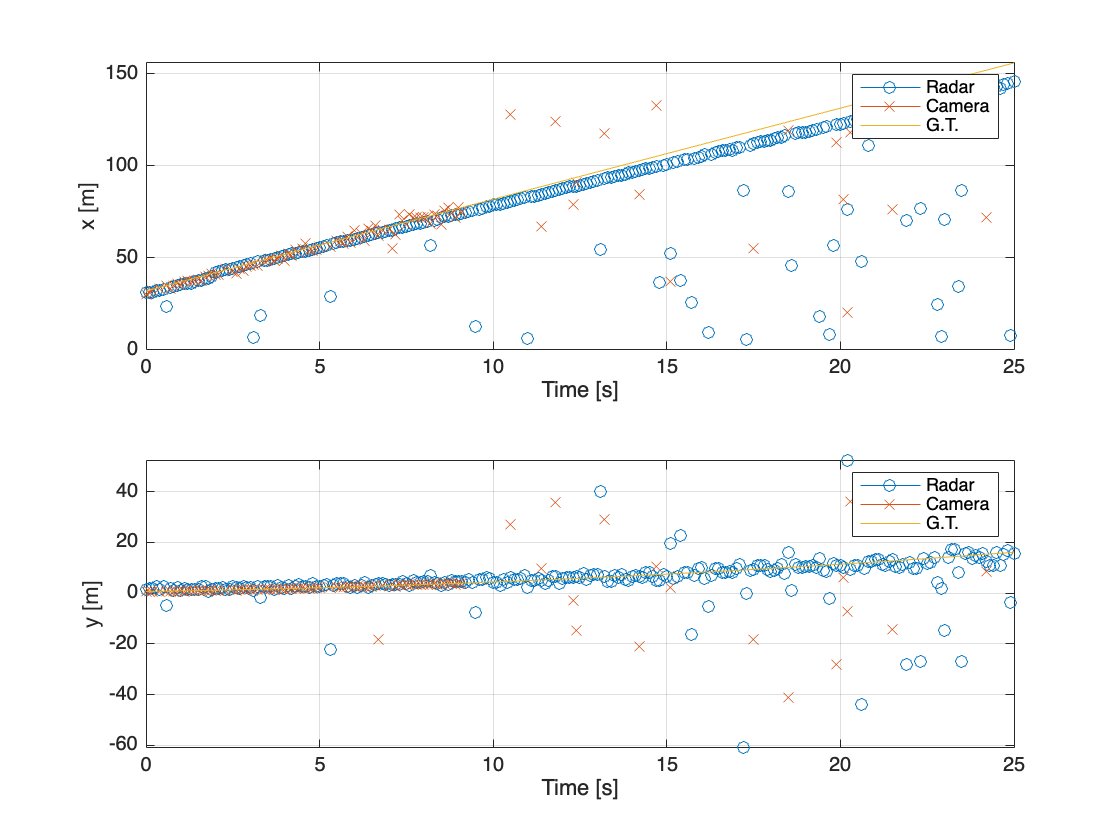

figure;

ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,radar_meas(:,1),"Marker","o");
plot(time_vec, camera_meas(:,1),"Marker","x");
plot(time_vec,GT(:,1));
ylabel("x [m]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,radar_meas(:,2),"Marker","o");
plot(time_vec, camera_meas(:,2),"Marker","x");
plot(time_vec,GT(:,2));
ylabel("y [m]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

### Relative Speed

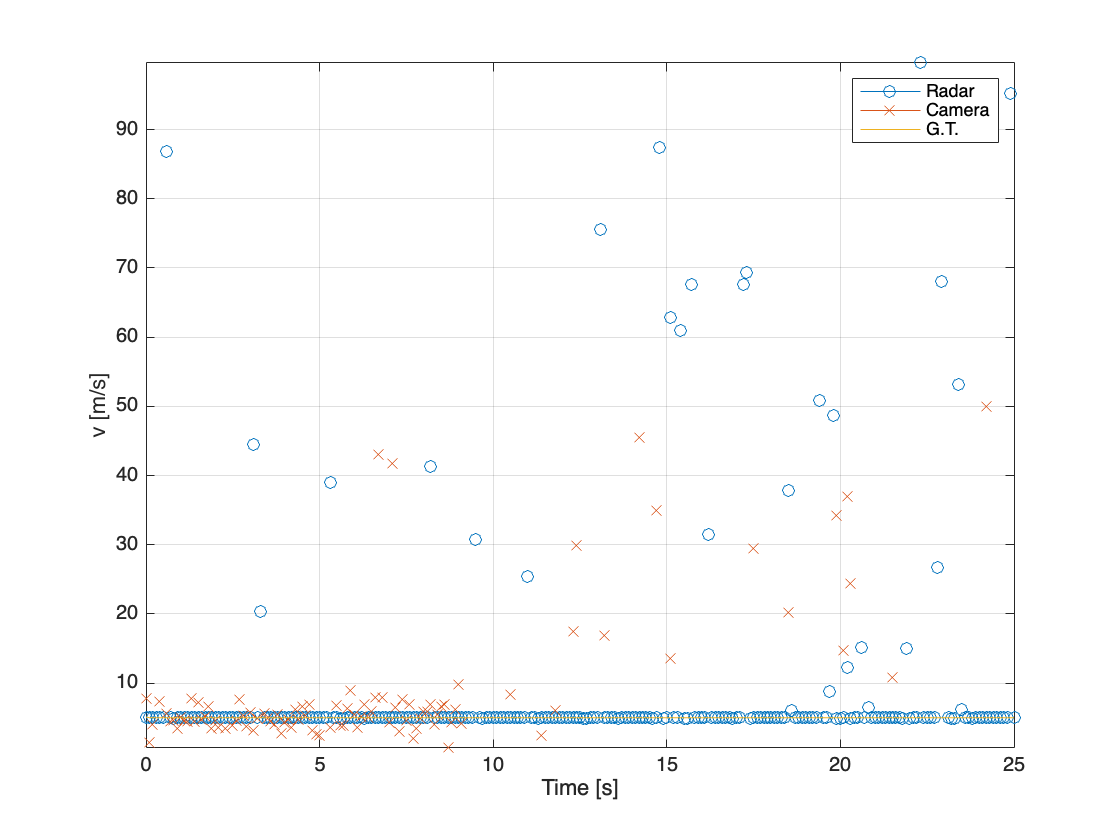

figure;

ax = [];

ax(1) = subplot(1,1,1); box on; hold on; grid on;
plot(time_vec,radar_speed,"Marker","o");
plot(time_vec, camera_speed,"Marker","x");
plot(time_vec,GT_speed);
ylabel("v [m/s]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

#### 
$$v_x$$


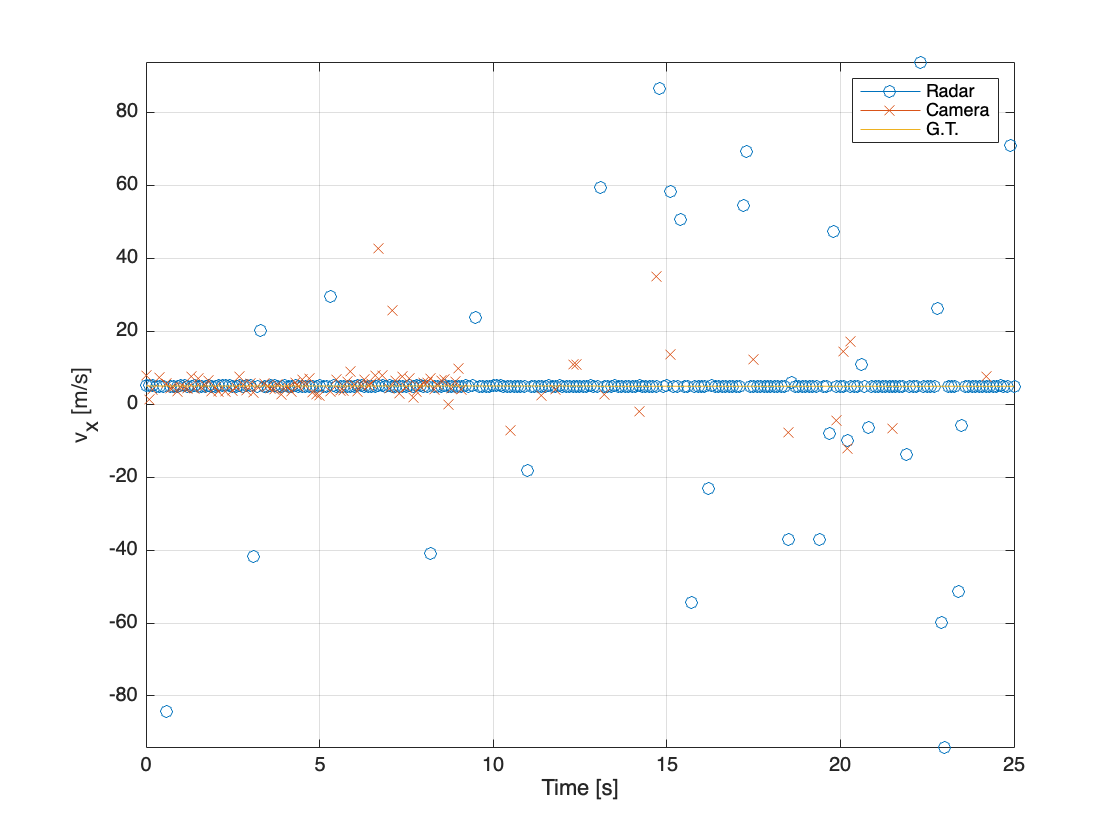

figure;

ax = [];

ax(1) = subplot(1,1,1); box on; hold on; grid on;
plot(time_vec,radar_meas(:,4),"Marker","o");
plot(time_vec, camera_meas(:,4),"Marker","x");
plot(time_vec,GT(:,4));
ylabel("v_x [m/s]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

#### 
$$v_y$$


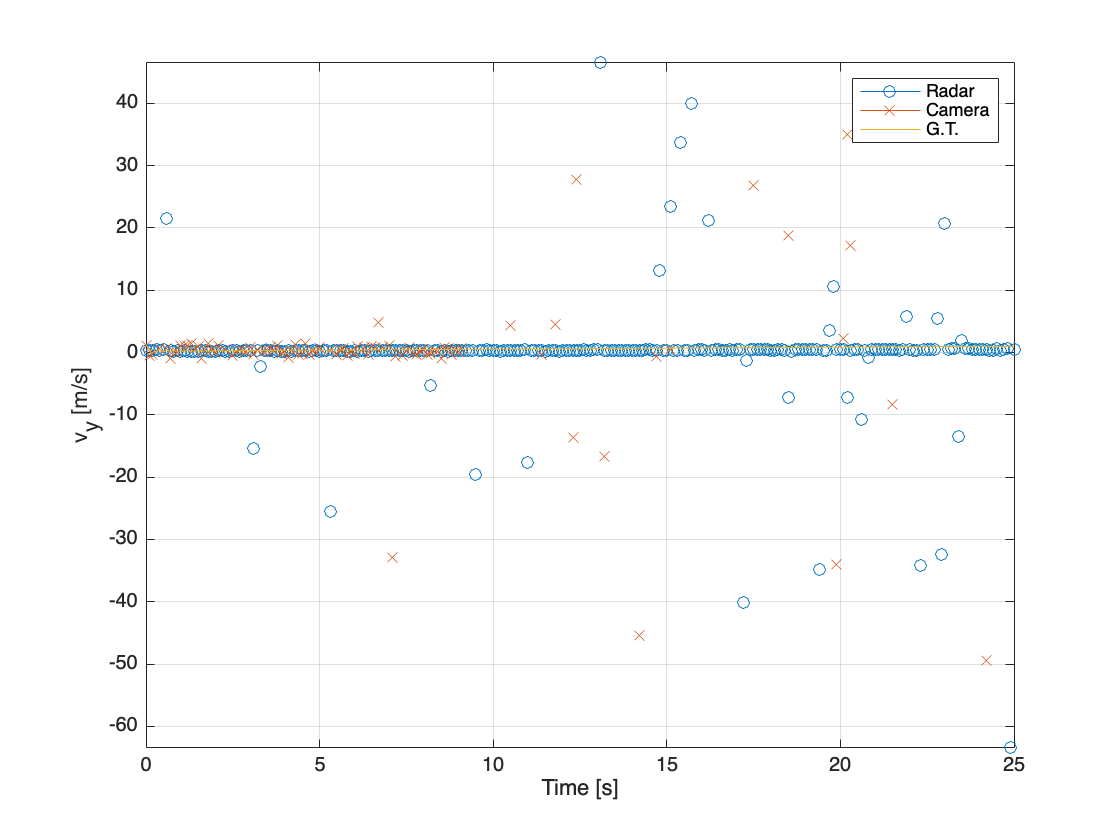

figure;

ax = [];

ax(1) = subplot(1,1,1); box on; hold on; grid on;
plot(time_vec,radar_meas(:,5),"Marker","o");
plot(time_vec, camera_meas(:,5),"Marker","x");
plot(time_vec,GT(:,5));
ylabel("v_y [m/s]");
xlabel("Time [s]");
legend("Radar", "Camera","G.T.");

linkaxes(ax, 'x');
axis tight;

## Plotting the GT State Vector of the vehicle over time

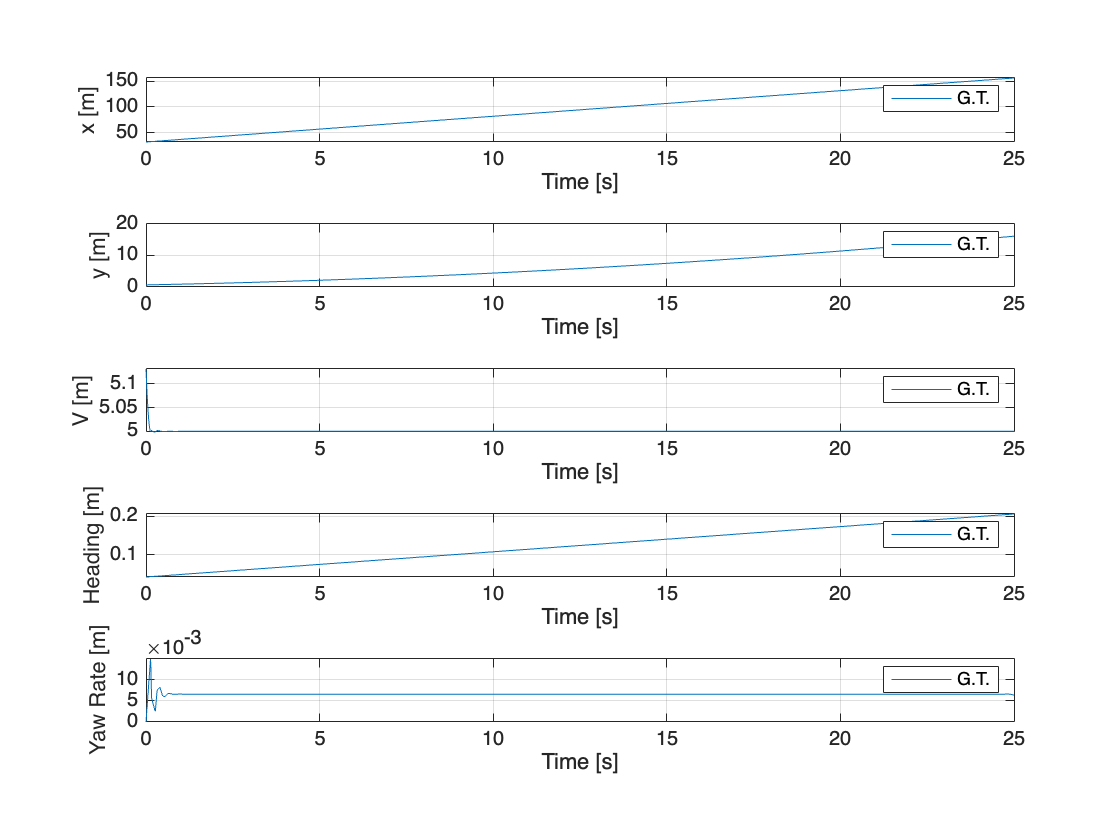

figure;

ax = [];

ax(1) = subplot(5,1,1); box on; hold on; grid on;
plot(time_vec,GT_state(:,1));
ylabel("x [m]");
xlabel("Time [s]");
legend("G.T.");

ax(2) = subplot(5,1,2); box on; hold on; grid on;
plot(time_vec,GT_state(:,2));
ylabel("y [m]");
xlabel("Time [s]");
legend("G.T.");

ax(3) = subplot(5,1,3); box on; hold on; grid on;
plot(time_vec,GT_state(:,3));
ylabel("V [m]");
xlabel("Time [s]");
legend("G.T.");

ax(4) = subplot(5,1,4); box on; hold on; grid on;
plot(time_vec,GT_state(:,4));
ylabel("Heading [m]");
xlabel("Time [s]");
legend("G.T.");

ax(5) = subplot(5,1,5); box on; hold on; grid on;
plot(time_vec,GT_state(:,5));
ylabel("Yaw Rate [m]");
xlabel("Time [s]");
legend("G.T.");

linkaxes(ax, 'x');
axis tight;

## Ego Vehicle State and Trajectory (World Frame)

### Position

ego_state_pos = ego_state.Position; % extact position
ego_state_pos  = squeeze(ego_state_pos.Data)'; % contains position
head(array2table(ego_state_pos,"VariableNames",{'x','y','z'})) % display first rows

     x        y       z
    ____    ______    _

       0    -761.8    0
    0.25    -761.8    0
     0.5    -761.8    0
    0.75    -761.8    0
       1    -761.8    0
    1.25    -761.8    0
     1.5    -761.8    0
    1.75    -761.8    0



### Velocity

ego_state_vel = ego_state.Velocity; % extact position
ego_state_vel  = squeeze(ego_state_vel.Data)'; % contains position
head(array2table(ego_state_vel,"VariableNames",{'v_x','v_y','v_z'})) % display first rows

    v_x      v_y       v_z
    ___    ________    ___

    25     0.037977     0 
    25     0.038302     0 
    25     0.039275     0 
    25     0.040897     0 
    25     0.043167     0 
    25     0.046087     0 
    25     0.049655     0 
    25     0.053871     0 



### Orientation

ego_state_or = ego_state.Orientation; % extact position
ego_state_or  = (pi/180)*squeeze(ego_state_or.Data)'; % contains position
EgoState = [ego_state_pos(:,1:2)';ego_state_or(:,3)'];
head(array2table(ego_state_or,"VariableNames",{'Roll','Pitch','Yaw'})) % display first rows

    Roll    Pitch       Yaw   
    ____    _____    _________

     0        0      0.0015191
     0        0      0.0015321
     0        0       0.001571
     0        0      0.0016359
     0        0      0.0017267
     0        0      0.0018435
     0        0      0.0019862
     0        0      0.0021549



### Angular Velocity

ego_state_ang_vel = ego_state.AngularVelocity; % extact position
ego_state_ang_vel  = (pi/180)*squeeze(ego_state_ang_vel.Data)'; % contains position

head(array2table(ego_state_ang_vel,"VariableNames",{'w_x','w_y','w_z'})) % display first rows

    w_x    w_y        w_z    
    ___    ___    ___________

     0      0     -2.8358e-10
     0      0       0.0025949
     0      0       0.0051898
     0      0       0.0077848
     0      0         0.01038
     0      0        0.012975
     0      0         0.01557
     0      0        0.018164



### Acceleration

ego_state_acc = ego_state.Acceleration; % extact position
ego_state_acc  = squeeze(ego_state_acc.Data)'; % contains position
head(array2table(ego_state_acc,"VariableNames",{'a_x','a_y','a_z'})) % display first rows

        a_x            a_y        a_z
    ___________    ___________    ___

      1.077e-11    -7.0896e-09     0 
     -9.939e-05       0.064873     0 
    -0.00020383        0.12975     0 
    -0.00031837        0.19462     0 
    -0.00044806        0.25949     0 
    -0.00059796        0.32437     0 
     -0.0007731        0.38924     0 
    -0.00097854        0.45411     0 



### Plot Values

#### Positions

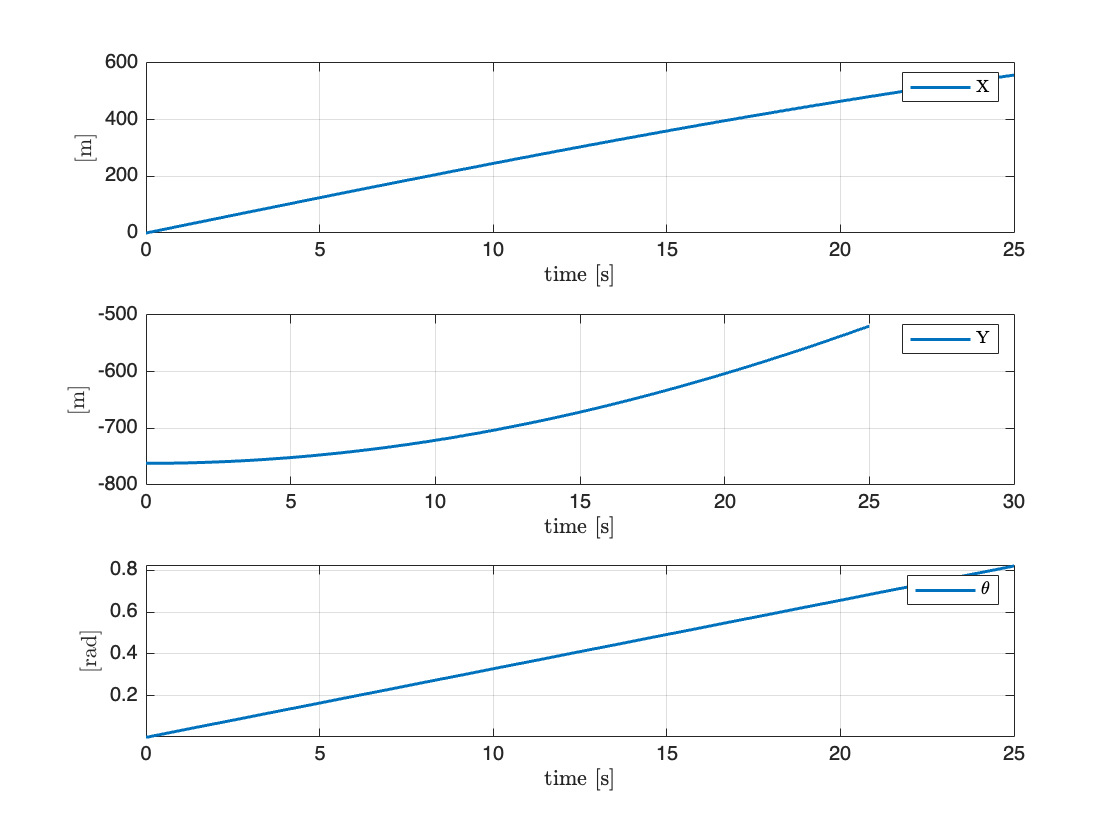

figure;

ax = [];

ax(1) = subplot(3,1,1); box on; hold on; grid on;
plot(time_vec,ego_state_pos(:,1),"LineWidth",1.5);
ylabel("[m]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("X",'Interpreter','latex');

ax(2) = subplot(3,1,2); box on; hold on; grid on;
plot(time_vec,ego_state_pos(:,2),"LineWidth",1.5);
ylabel("[m]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("Y",'Interpreter','latex');

ax(2) = subplot(3,1,3); box on; hold on; grid on;
plot(time_vec,ego_state_or(:,3),"LineWidth",1.5);
ylabel("[rad]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$\theta$",'Interpreter','latex');

linkaxes(ax, 'x');
axis tight;

#### Velocities

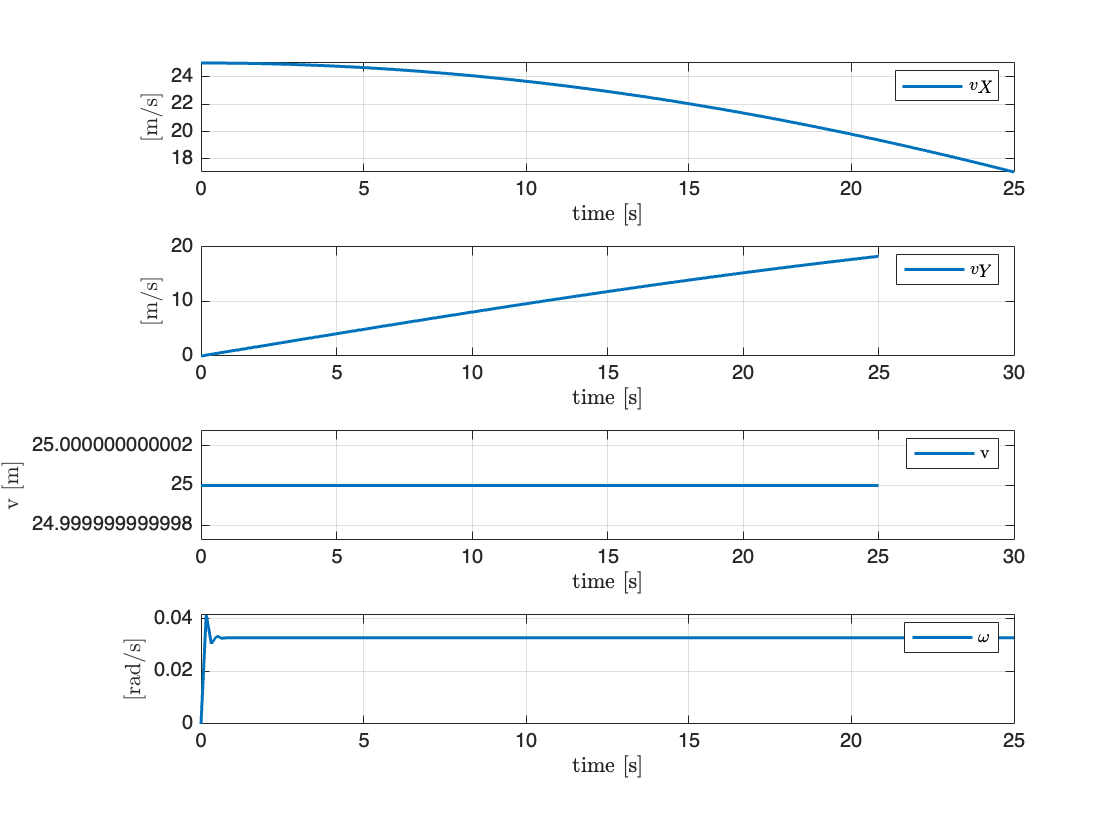

figure;

ax = [];

ax(1) = subplot(4,1,1); box on; hold on; grid on;
plot(time_vec,ego_state_vel(:,1),"LineWidth",1.5);
ylabel("[m/s]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$v_X$",'Interpreter','latex');

ax(2) = subplot(4,1,2); box on; hold on; grid on;
plot(time_vec,ego_state_vel(:,2),"LineWidth",1.5);
ylabel("[m/s]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$v_Y$",'Interpreter','latex');

ax(2) = subplot(4,1,3); box on; hold on; grid on;
plot(time_vec,sqrt(ego_state_vel(:,2).^2 + ego_state_vel(:,1).^2),"LineWidth",1.5);
ylabel("v [m]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("v",'Interpreter','latex');

ax(2) = subplot(4,1,4); box on; hold on; grid on;
plot(time_vec,ego_state_ang_vel(:,3),"LineWidth",1.5);
ylabel("[rad/s]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$\omega$",'Interpreter','latex');

linkaxes(ax, 'x');
axis tight;

#### Accelerations

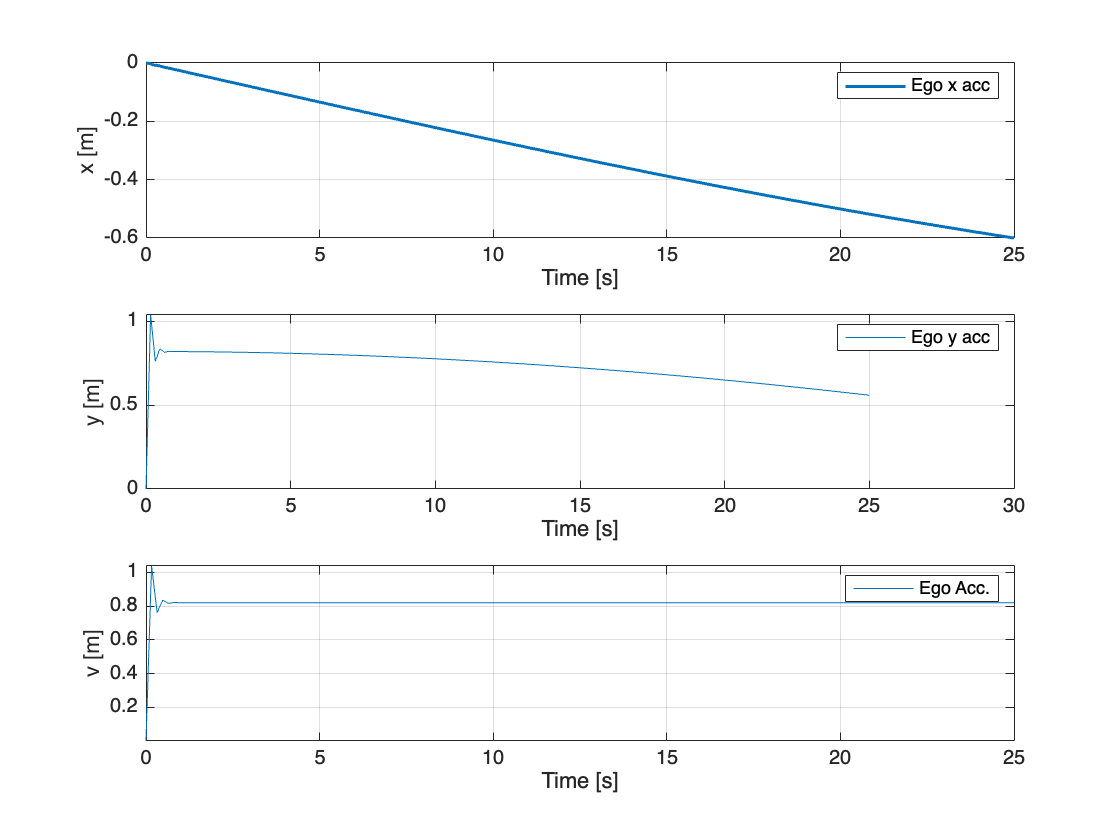

figure;

ax = [];

ax(1) = subplot(3,1,1); box on; hold on; grid on;
plot(time_vec,ego_state_acc(:,1),"LineWidth",1.5);
ylabel("x [m]");
xlabel("Time [s]");
legend("Ego x acc");

ax(2) = subplot(3,1,2); box on; hold on; grid on;
plot(time_vec,ego_state_acc(:,2));
ylabel("y [m]");
xlabel("Time [s]");
legend("Ego y acc");

ax(2) = subplot(3,1,3); box on; hold on; grid on;
plot(time_vec,sqrt(ego_state_acc(:,2).^2 + ego_state_acc(:,1).^2));
ylabel("v [m]");
xlabel("Time [s]");
legend("Ego Acc.");

linkaxes(ax, 'x');
axis tight;

## Target Vehicle State and Trajectory (World Frame)

target_state_pos = target_state.Position; % extact position
target_state_pos  = squeeze(target_state_pos.Data)'; % contains position
head(array2table(target_state_pos,"VariableNames",{'x','y','z'})) % display first rows

      x          y       z
    ______    _______    _

    32.061    -761.13    0
    32.361    -761.11    0
    32.661     -761.1    0
     32.96    -761.09    0
     33.26    -761.07    0
     33.56    -761.06    0
    33.859    -761.05    0
    34.159    -761.03    0



### Velocity

target_state_vel = target_state.Velocity; % extact position
target_state_vel  = squeeze(target_state_vel.Data)'; % contains position
head(array2table(target_state_vel,"VariableNames",{'v_x','v_y','v_z'})) % display first rows

     v_x       v_y      v_z
    ______    ______    ___

    29.971    1.3081     0 
    29.971    1.3087     0 
    29.971    1.3103     0 
    29.971    1.3131     0 
    29.971    1.3171     0 
    29.971    1.3221     0 
    29.971    1.3283     0 
     29.97    1.3355     0 



### Orientation

target_state_or = target_state.Orientation; % extact position
target_state_or  = (pi/180)*squeeze(target_state_or.Data)'; % contains position
head(array2table(target_state_or,"VariableNames",{'Roll','Pitch','Yaw'})) % display first rows

    Roll    Pitch      Yaw   
    ____    _____    ________

     0        0      0.043617
     0        0      0.043636
     0        0      0.043692
     0        0      0.043786
     0        0      0.043916
     0        0      0.044085
     0        0       0.04429
     0        0      0.044533



### Angular Velocity

target_state_ang_vel = target_state.AngularVelocity; % extact position
target_state_ang_vel  = (pi/180)*squeeze(target_state_ang_vel.Data)'; % contains position
head(array2table(target_state_ang_vel,"VariableNames",{'w_x','w_y','w_z'})) % display first rows

    w_x    w_y       w_z    
    ___    ___    __________

     0      0     -3.403e-10
     0      0      0.0037367
     0      0      0.0074734
     0      0        0.01121
     0      0       0.014947
     0      0       0.018683
     0      0        0.02242
     0      0       0.026157



### Acceleration

target_state_acc = target_state.Acceleration; % extact position
target_state_acc  = squeeze(target_state_acc.Data)'; % contains position
head(array2table(target_state_acc,"VariableNames",{'a_x','a_y','a_z'})) % display first rows

       a_x            a_y        a_z
    __________    ___________    ___

    4.4515e-10    -1.0199e-08     0 
    -0.0048901        0.11199     0 
    -0.0097927        0.22399     0 
     -0.014721        0.33598     0 
     -0.019686        0.44797     0 
     -0.024702        0.55996     0 
      -0.02978        0.67194     0 
     -0.034934        0.78393     0 



% GT_state = [target_state_pos(:,1:2),sqrt(target_state_vel(:,1).^2+target_state_vel(:,2).^2),target_state_or(:,3),target_state_ang_vel(:,3)];
% GT_speed = GT_state(:,3); 

### Plot Values

#### Positions

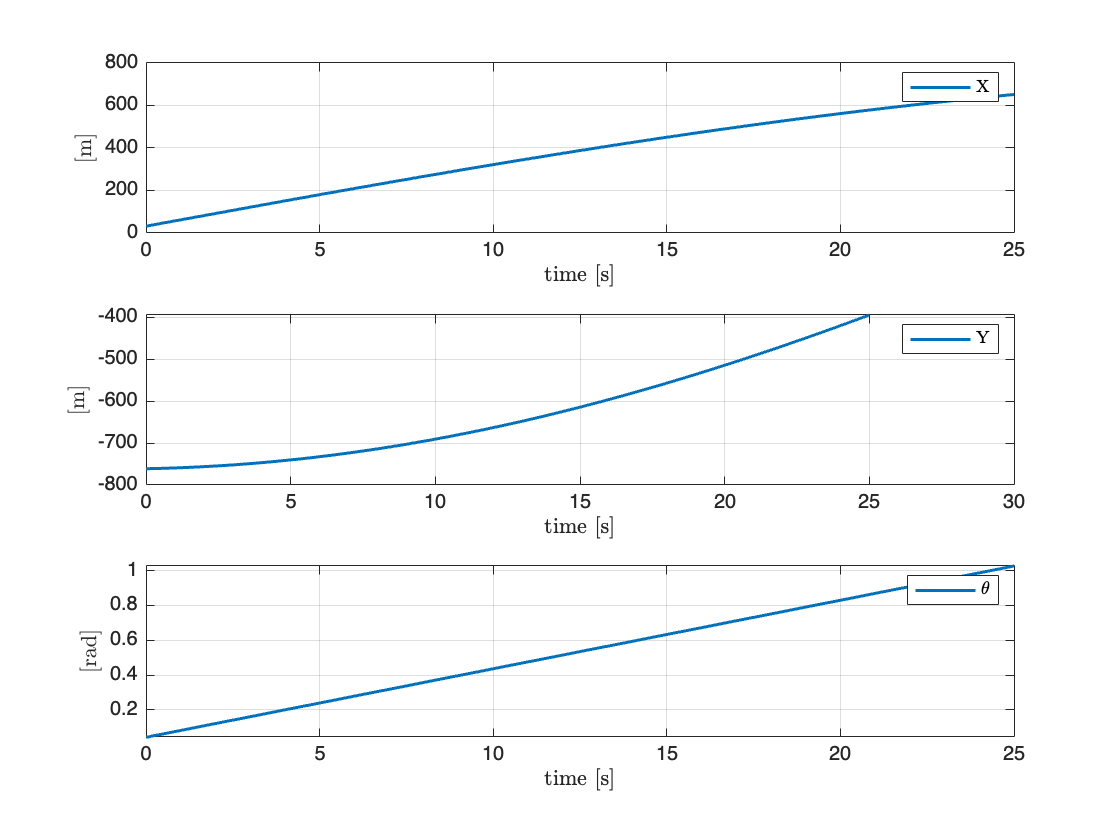

figure;

ax = [];

ax(1) = subplot(3,1,1); box on; hold on; grid on;
plot(time_vec,target_state_pos(:,1),"LineWidth",1.5);
ylabel("[m]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("X",'Interpreter','latex');

ax(2) = subplot(3,1,2); box on; hold on; grid on;
plot(time_vec,target_state_pos(:,2),"LineWidth",1.5);
ylabel("[m]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("Y",'Interpreter','latex');

ax(2) = subplot(3,1,3); box on; hold on; grid on;
plot(time_vec,target_state_or(:,3),"LineWidth",1.5);
ylabel("[rad]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$\theta$",'Interpreter','latex');

linkaxes(ax, 'x');
axis tight;

#### Velocities

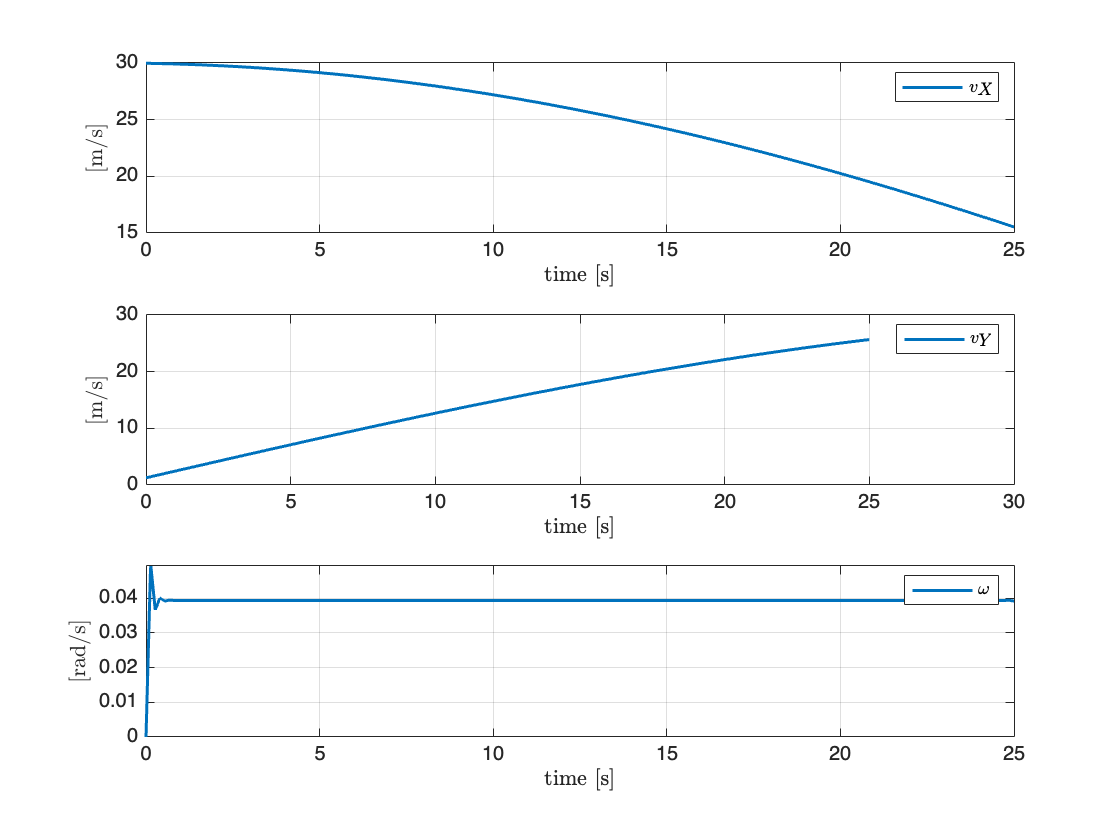

figure;

ax = [];

ax(1) = subplot(3,1,1); box on; hold on; grid on;
plot(time_vec,target_state_vel(:,1),"LineWidth",1.5);
ylabel("[m/s]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$v_X$",'Interpreter','latex');

ax(2) = subplot(3,1,2); box on; hold on; grid on;
plot(time_vec,target_state_vel(:,2),"LineWidth",1.5);
ylabel("[m/s]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$v_Y$",'Interpreter','latex');

ax(2) = subplot(3,1,3); box on; hold on; grid on;
plot(time_vec,target_state_ang_vel(:,3),"LineWidth",1.5);
ylabel("[rad/s]",'Interpreter','latex');
xlabel("time [s]",'Interpreter','latex');
legend("$\omega$",'Interpreter','latex');

linkaxes(ax, 'x');
axis tight;

#### Accelerations

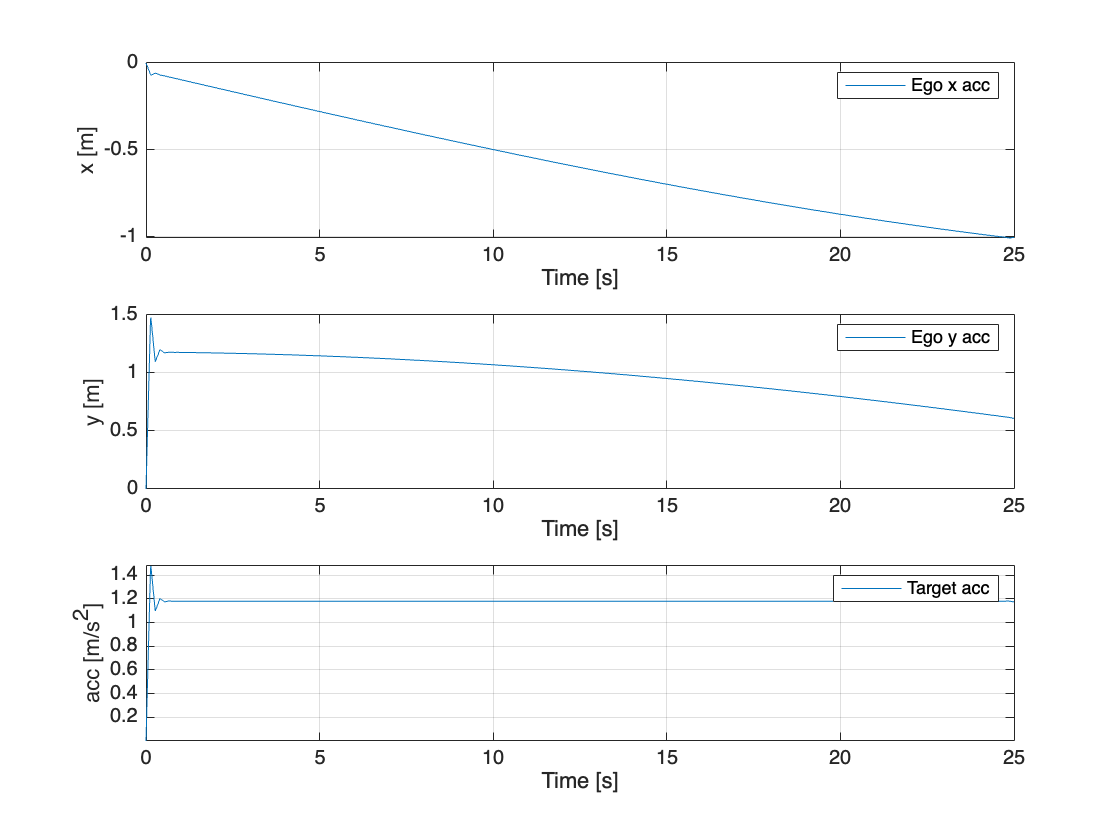

figure;
target_tot_acc = sqrt(target_state_acc(:,1).^2 + target_state_acc(:,2).^2);
ax = [];

ax(1) = subplot(3,1,1); box on; hold on; grid on;
plot(time_vec,target_state_acc(:,1));
ylabel("x [m]");
xlabel("Time [s]");
legend("Ego x acc");

ax(2) = subplot(3,1,2); box on; hold on; grid on;
plot(time_vec,target_state_acc(:,2));
ylabel("y [m]");
xlabel("Time [s]");
legend("Ego y acc");

ax(3) = subplot(3,1,3); box on; hold on; grid on;
plot(time_vec,target_tot_acc);
ylabel("acc [m/s^2]");
xlabel("Time [s]");
legend("Target acc");

linkaxes(ax, 'x');
axis tight;

## Sensor Measurement Noises

The `MeasurementNoise` field is a 6-by-6 matrix that reports the measurement noise covariance for each coordinate in the `Measurement` field. On the diagonal we have the variance. 

We can simplify everything by considering only the variance and considering as 0 the covariances between the components.

### Camera

camera_noise = camera_data.Detections.MeasurementNoise;
camera_noise = camera_noise.Data; % take the matrices
camera_noise_Var = NaN(length(camera_noise),6);
camera_noise_Sigma = NaN(length(camera_noise),6);
for ii = 1:10:length(camera_noise)
    camera_noise_Var(ii,:) = diag(camera_noise(:,:,ii))'; % isolating the variance
    camera_noise_Sigma(ii,:) = sqrt(camera_noise_Var(ii,:)); % computing the std. dev.
end

% compute mean variance for each measured variable
% compute mean variance for each measured variable
mean_var_x_camera = mean(camera_noise_Var(~isnan(camera_noise_Var(1:2500,1)),1));
mean_var_y_camera = mean(camera_noise_Var(~isnan(camera_noise_Var(1:2500,2)),2));
mean_var_v_x_camera = mean(camera_noise_Var(~isnan(camera_noise_Var(1:2500,4)),4));
mean_var_v_y_camera = mean(camera_noise_Var(~isnan(camera_noise_Var(1:2500,5)),5));

R_camera_var = diag([mean_var_x_camera,mean_var_y_camera,mean_var_v_x_camera,mean_var_v_y_camera]);

### Radar

radar_noise = radar_data.Detections.MeasurementNoise;
radar_noise = radar_noise.Data; % take the matrices
radar_noise_Var = NaN(length(camera_noise),6);
radar_noise_Sigma = NaN(length(camera_noise),6);
for ii = 1:10:length(radar_noise)
    radar_noise_Var(ii,:) = diag(radar_noise(:,:,fix(ii/11)+1))'; % isolating the variance
    radar_noise_Sigma(ii,:) = sqrt(radar_noise_Var(ii,:)); % computing the std. dev.
end

% compute mean variance for each measured variable
mean_var_x_radar = mean(radar_noise_Var(~isnan(radar_noise_Var(1:2500,1)),1));
mean_var_y_radar = mean(radar_noise_Var(~isnan(radar_noise_Var(1:2500,2)),2));
mean_var_v_x_radar = mean(radar_noise_Var(~isnan(radar_noise_Var(1:2500,4)),4));
mean_var_v_y_radar = mean(radar_noise_Var(~isnan(radar_noise_Var(1:2500,5)),5));

R_radar_var = diag([mean_var_x_radar,mean_var_y_radar,mean_var_v_x_radar,mean_var_v_y_radar]);

## Plot Lateral and Longitudinal Position and Velocity errors for both sensors in the same plot 

To be completed

% GT, meas -> error
% std dev associated to noise to plot on the same graph
camera_error = computeError(GT,camera_meas);
radar_error = computeError(GT,radar_meas);

### Position

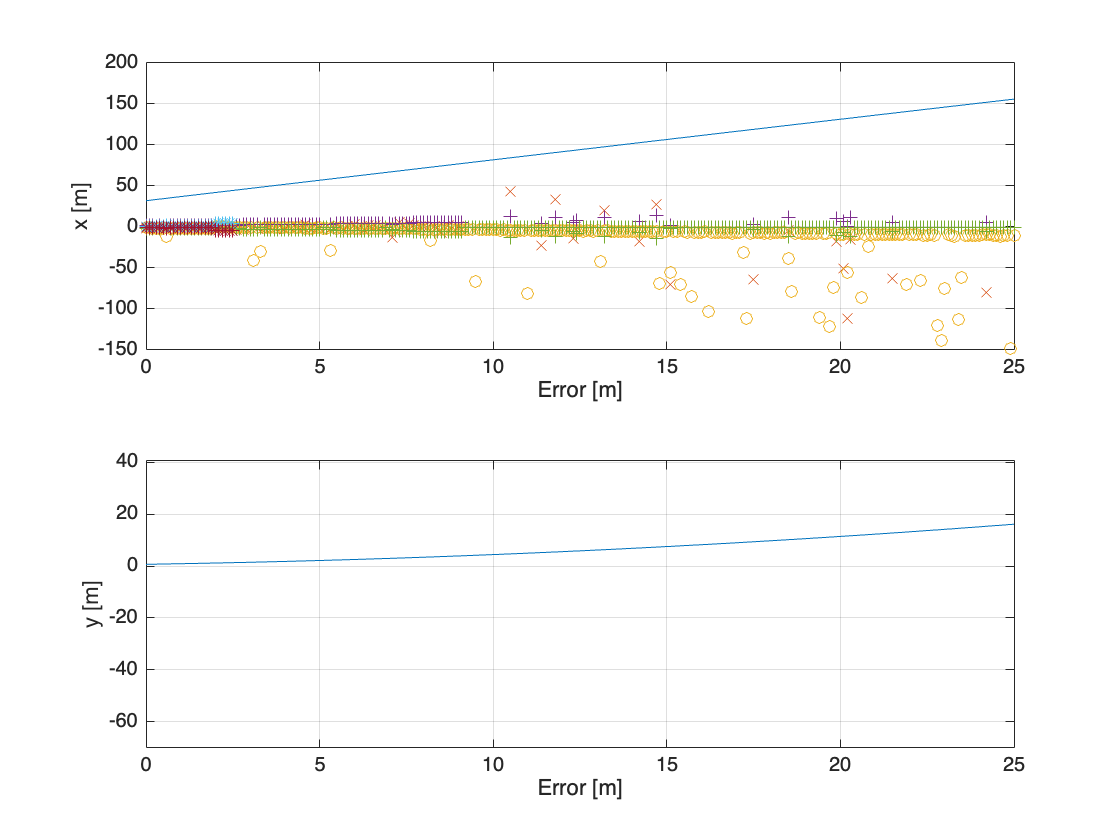

figure;

ax = [];

ax(1) = subplot(2,1,1); box on; hold on; grid on;
plot(time_vec,GT(:,1));
plot(time_vec,camera_error(:,1),"Marker","x");
plot(time_vec,radar_error(:,1),"Marker","o");
plot(time_vec,2*camera_noise_Sigma(:,1),"Marker","+")
plot(time_vec,-2*camera_noise_Sigma(:,1),"Marker","+");
plot(time_vec,2*radar_noise_Sigma(:,1),"Marker","*")
plot(time_vec,-2*radar_noise_Sigma(:,1),"Marker","*");
ylabel("x [m]");
xlabel("Error [m]");
% legend("");

ax(2) = subplot(2,1,2); box on; hold on; grid on;
plot(time_vec,GT(:,2),time_vec,camera_error(:,2),time_vec,radar_error(:,2));
ylabel("y [m]");
xlabel("Error [m]");
% legend("Ego y acc");

linkaxes(ax, 'x');
axis tight;

### Saving data variables as arrays for convenience

if Urban
    save("Urban_time_vector.mat","time_vec");
    save("Urban_camera_meas_array.mat","camera_meas");
    save("Urban_camera_speed_array.mat","camera_speed");
    save("Urban_radar_meas_array.mat","radar_meas");
    save("Urban_radar_speed_array.mat","radar_speed");
    save("Urban_GT_array.mat","GT");
    save("Urban_GT_speed_array.mat","GT_speed");
    save("Urban_GT_state.mat","GT_state");
else
    save("HW_time_vector.mat","time_vec");
    save("HW_camera_meas_array.mat","camera_meas");
    save("HW_camera_speed_array.mat","camera_speed");
    save("HW_radar_meas_array.mat","radar_meas");
    save("HW_radar_speed_array.mat","radar_speed");
    save("HW_GT_array.mat","GT");
    save("HW_GT_speed_array.mat","GT_speed");
    save("HW_GT_state.mat","GT_state");
    save("HW_EgoState.mat","EgoState");
    save("HW_Radar_mean_var.mat","R_radar_var")
    save("HW_Camera_mean_var.mat","R_camera_var")

end

## Auxiliary Functions

function error = computeError(groundTruth,meas)
         
         error = meas-groundTruth;

end